%% AUTHOR INFORMATION
% NAME: Balaji V
% EMAIL: ee19d2020@smail.iitm.ac.in
% Code to analyse the output from ./Test_Write_Drivers

## Preface

    clear ;
    clc ;
    if( ~exist( 'globalVars', 'var' ) )
        globalVars=[];
    end
    eval( [ 'clearvars -except globalVars ' sprintf( '%s ', globalVars ) ] ) ;
    close all ;
    zeroes = @( x ) zeros( x ) ;
    addpath("D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\lowerLevelCode\FPGA_COMMUNICATE");
    addpath("D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\lowerLevelCode\FPGA_CONTROL");
    addpath("D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\lowerLevelCode\MISC");
    addpath("D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\lowerLevelCode\POWER_SUPPLY_CONTROL");


## Go to Global

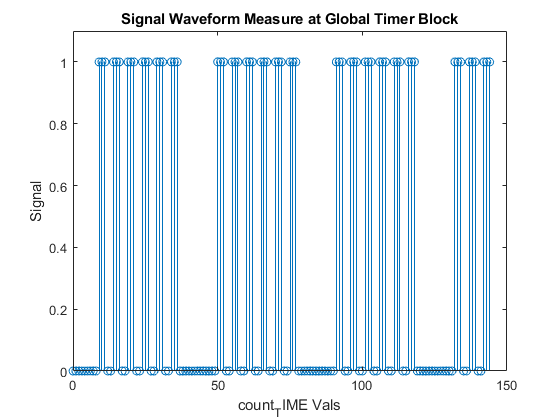

% Global : D:\Xilinx\Vivado_2018_Projs\Srinidhi_Laptop\PCB_TEST_FPGA_ARM\Character_Files\new_C_code_UART_files\10_vecfile_auto_FA\7_vecfile_auto_FA
% cd( '../../../' ) ;
%     fileName = mfilename ; 
    filePath = matlab.desktop.editor.getActiveFilename ;
    b = find( filePath == '\', 1, 'last' ) ; 
    fileName = filePath( ( b + 1 )  : ( end - 4 ) ) ;
    b = find( fileName == '_', 1, 'last' ) ; 
    sourceFileName = fileName( 1 : ( b - 1 ) ) ;
driverCode_fileName         = sprintf( '/%s', sourceFileName ) ;
filePath            = '.' ;
fpgaReceivedFile_name       = [ filePath '/fpgaRcvdFiles' driverCode_fileName ] ;
[    fpgaReceivedFile_decrypted ...
            , adc_VPVN ...
            , adc_AUX00 ...
            ,    SA_SC_collect    ...
            ,    ADC_SC_collect  ...
            ,    AdderTree_SC_collect  ...
            ,    SARTIMING_OUT_SC_collect  ...
            ,    WRITE_2_SC_collect  ...
            ,    WRITE_1_SC_collect  ...
            ,    WRITE_0_SC_collect  ...
            ,    IMC_RBL_SC_collect  ...
            ,    IMC_VOut_SC_collect  ...
            ,    WWL_SC_collect  ...
            ,    FLOATADC_SC_collect  ...
            ,    SARTIMING_IN_SC_collect  ...
            ,    ControlPath_SC_collect  ...
            ,    Reset_DFF_collect  ...
            ,    SAR_Bin_Num ...
            ,     read_SRAM_collect_Cell...
            ,    perform_hybridIMC_BLIMG_FPGA_collect...
            ,    perform_internalIMC_ImgBankFPGA_collect  ] = decrypt_and_RSC( fpgaReceivedFile_name ) ;
%% cd'ing back
    cd( filePath ) ;
%% saving data
    c = clock ;
    year    = c(1) ;
    month   = c(2) ; 
    day     = c(3) ;
    hour    = c(4) ;
    minute  = c(5) ;
    seconds = floor(c(6)) ;
save( [ sprintf( './analyzeResults/%s_%s_%d_%d_%d', fileName, date,hour,minute,seconds) ] ) ;
DATA_CM_EN = 1;
DATA_SUB_EN = 2;
REF_CM_EN = 3;
REF_SUB_EN = 4;
RWL_EN = 5;
ADC_DONE = 6;
AllVIN_n = 7;
BL_Sel_Dec_2 = 8;
BL_Sel_Dec_1 = 9;
BL_Sel_Dec_0 = 10;
CLK_DFF = 11;
CLK_SARLOGIC_IN = 12;
PRE_VCM = 13;
Reset_SARLOGIC = 14;
SA_EN = 15;
count_TIME_0 = 16;
count_TIME_1 = 17;
count_TIME_2 = 18;
count_TIME_3 = 19;
count_TIME_4 = 20;
count_TIME_5 = 21;
count_TIME_6 = 22;
count_TIME_7 = 23;
count_TIME_8 = 24;
count_TIME_9 = 25;
count_TIME_10 = 26;

prompt_val=input('Enter the signal to be plotted:\n','s');

figure();
stem([0:144],SARTIMING_OUT_SC_collect(:,eval(prompt_val)));
title('Signal Waveform Measure at Global Timer Block');
ylim([0 1.1]);
xlabel('count_TIME Vals');
ylabel('Signal');